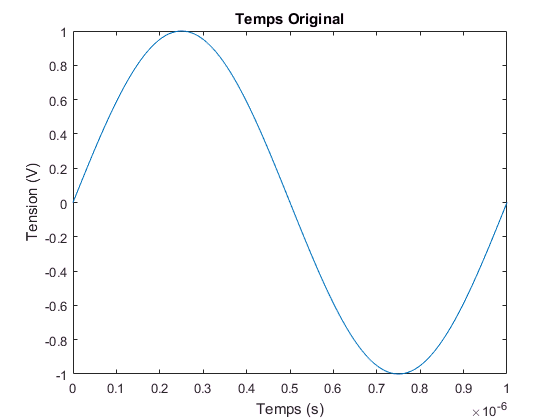

% Martelet / Yin

clc
close all

% Partie B
f = 1e6;


t = linspace(0,1/f,2^7);
s = sin(2*pi*f*t);
plot(t,s);
title('Temps Original')
xlabel('Temps (s)');ylabel('Tension (V)');

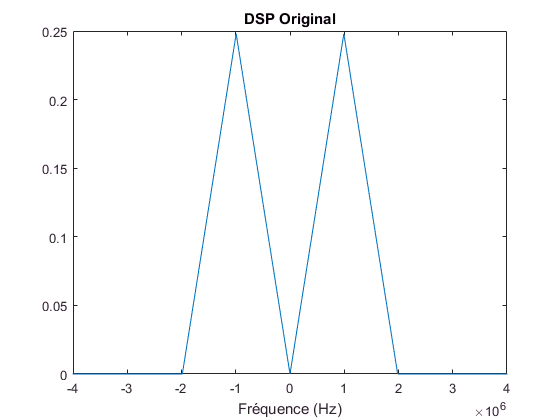


[F,S] = fft_eea(t,s);
plot(F,abs(S).^2);
xlim([-4*1e6 4*1e6])
title('DSP Original')
xlabel('Fréquence (Hz)');

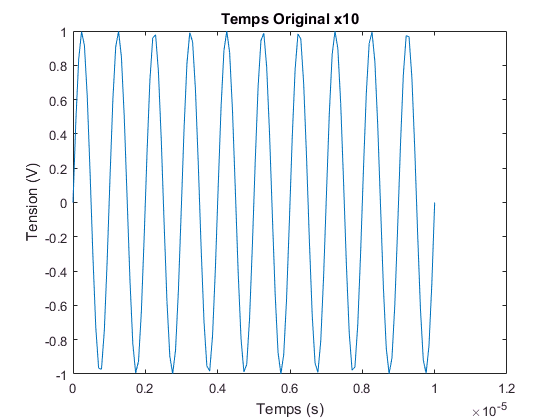


t = linspace(0,10/f,2^7);
s = sin(2*pi*f*t);
plot(t,s);
title('Temps Original x10')
xlabel('Temps (s)');ylabel('Tension (V)');

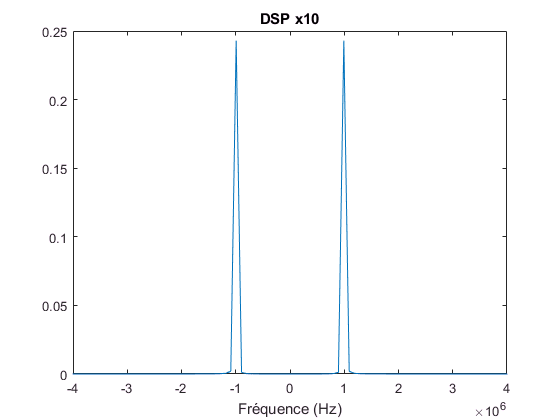


[F,S] = fft_eea(t,s);
plot(F,abs(S).^2);
xlim([-4*1e6 4*1e6])
title('DSP x10')
xlabel('Fréquence (Hz)');

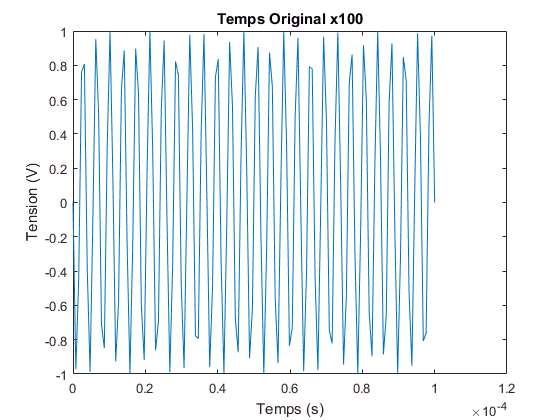


t = linspace(0,100/f,2^7);
s = sin(2*pi*f*t);
% plot(t,s);
plot(t,s)
title('Temps Original x100')
xlabel('Temps (s)');ylabel('Tension (V)');

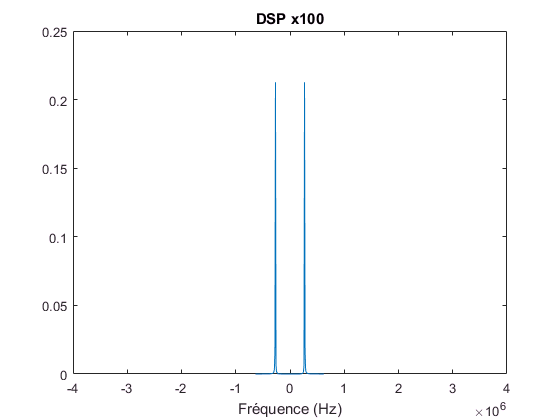


[F,S] = fft_eea(t,s);
plot(F,abs(S).^2);
xlim([-4*1e6 4*1e6])
title('DSP x100')
xlabel('Fréquence (Hz)');

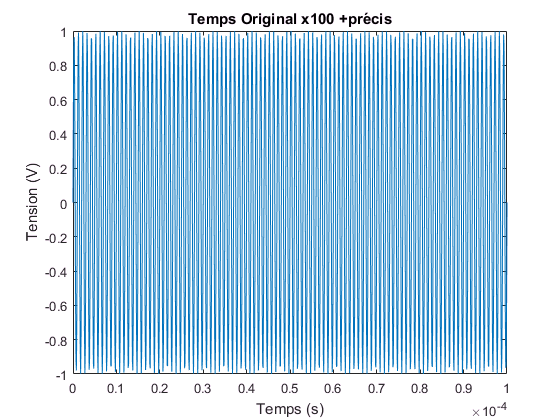


t = linspace(0,100/f,2^10);
s = sin(2*pi*f*t);
plot(t,s);
title('Temps Original x100 +précis')
xlim([0 1e-4])
xlabel('Temps (s)');ylabel('Tension (V)');

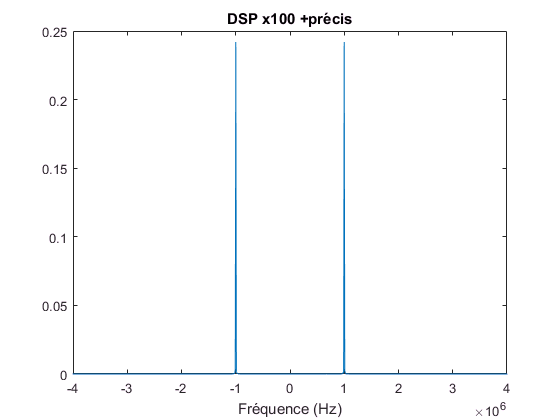


[F,S] = fft_eea(t,s);
plot(F,abs(S).^2);
xlim([-4*1e6 4*1e6])
title('DSP x100 +précis')
xlabel('Fréquence (Hz)');

% Partie C

t = 0:5*1e-6:0.1

t =    1.0e-03 *

         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


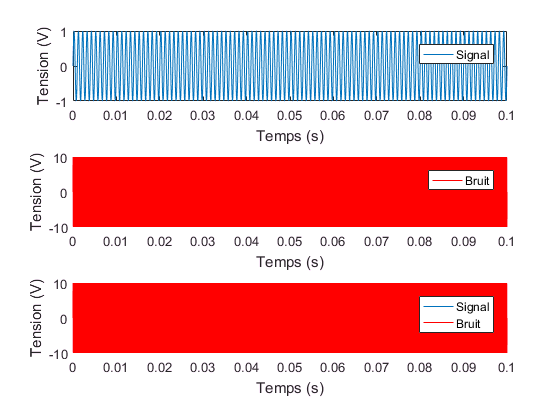

s = sin(2*pi*1e3*t);
b = 10*sin(2*pi*10*1e3*t);

figure % Tracé des signaux
subplot(3,1,1)
plot(t,s)
legend('Signal')
xlabel('Temps (s)');
ylabel('Tension (V)');
subplot(3,1,2)
plot(t,b,'r')
legend('Bruit')
xlabel('Temps (s)');
ylabel('Tension (V)');
subplot(3,1,3)
plot(t,s,t,b,'r')
legend('Signal','Bruit')
xlabel('Temps (s)');
ylabel('Tension (V)');

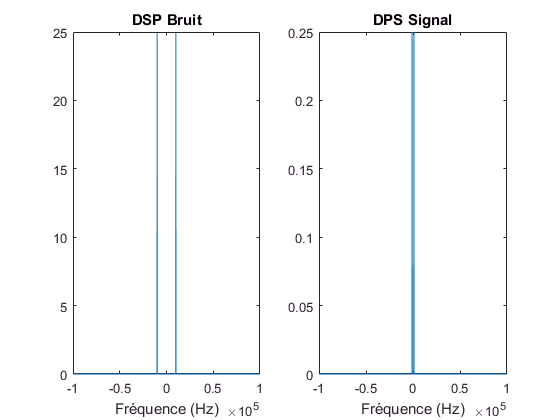



[F,S] = fft_eea(t,s);
[F,B] = fft_eea(t,b);

figure
subplot(1,2,1)
plot(F,abs(B).^2);
xlim([-1e5 1e5])
xlabel('Fréquence (Hz)');
title('DSP Bruit')
subplot(1,2,2)
plot(F,abs(S).^2);
xlim([-1e5 1e5])
xlabel('Fréquence (Hz)');
title('DPS Signal')


[D_max,n] = max(S);
f_max = F(n)

f_max = -999.9695

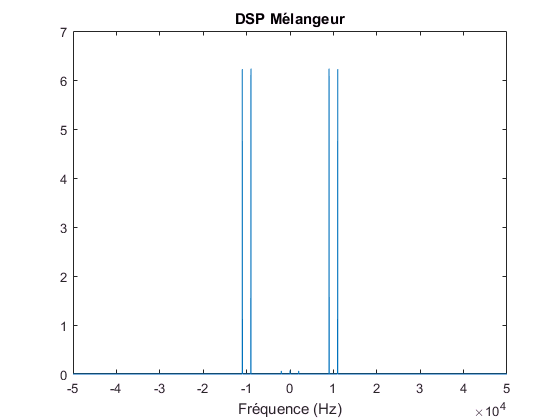


% Mélangeur
m = (s+b).*sin(2*pi*1e3*t+1);
[F,M] = fft_eea(t,m);

figure
plot(F,abs(M).^2)
xlim([-0.5*1e5 0.5*1e5])
xlabel('Fréquence (Hz)');
title('DSP Mélangeur')